푸리에 변환

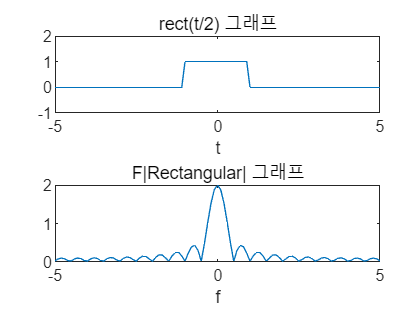

dt=0.1;
t=-5:dt:5; % 시간축 설정
x=stepfun(t,-1)-stepfun(t,1); % 사각 펄스 신호 생성
ft=fftshift(fft(x))*dt; % x(t)의 푸리에 변환 수행
subplot(2,1,1); plot(t,x); % 시간 영역 결과를 그림
title('rect(t/2) 그래프'); % 그림 제목
axis([-5 5 -1 2]); xlabel('t'); % 그림 영역 설정 및 x축 라벨 표시
subplot(2,1,2), plot(t,abs(ft)); % FT에 의한 주파수 영역 결과를 그림
title('F|Rectangular| 그래프'); % 그림 제목
axis([-5 5 0 2]); xlabel('f'); % 그림 영역 설정 및 x축 라벨 표시